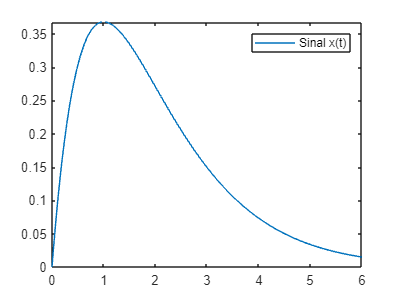

%Questão 01
%SF exp complexa
t0 = 0;
T = 6;
w = 2*pi/T;
syms t;
x = t*exp(-t);
figure
fplot(x, [t0, t0+T])
legend("Sinal x(t)")

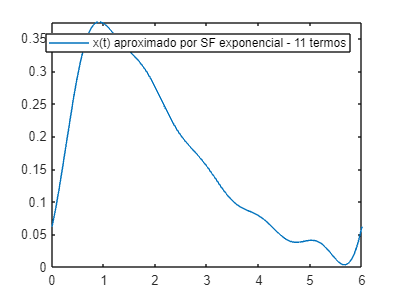

%aproximando utilizando 11 termos 
k = -5:5;
a = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
ex = exp(j*k*w*t);

xxe = sum(a.*ex);
figure
fplot(xxe, [t0, t0+T])
legend("x(t) aproximado por SF exponencial - 11 termos")

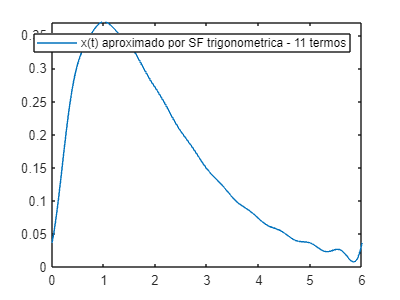

%SF forma trigonometrica
T = 6;
t0 = 0;
w = 2*pi/T;
syms t
x = t*exp(-t);
a0 = (1/T) * int(x, t, t0, t0+T);
n= 1:10;
b = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
c = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);

k = 1:10;
xxt = a0 + sum(b.*cos(k*w*t) + c.*sin(k*w*t));
figure
fplot(xxt, [t0, t0+T])
legend("x(t) aproximado por SF trigonometrica - 11 termos")

%Comparação
t1 = 0:0.1:6;
xxt = subs(xxt, t, t1)
xxe = subs(xxe, t, t1)
plot(t1, xxt, t1, xxe)

%Questao 02

%Forma exp complexa 2
t0 = -3;
T = 6;
w = 2*pi/T;
syms t
x = exp(-t);

k = -6:6;
a_exp = 1/T * int(x*exp(-j*k*w*t), t, t0, t0+T);
ex = exp(j*k*w*t);

xe = sum(a_exp.*ex);

%SF forma trigonometrica 2
T = 6;
t0 = -3;
w = 2*pi/T;
syms t
x = exp(-t);
a0 = (1/T) * int(x, t, t0, t0+T);
n= 1:10;
b = (2/T) * int(x*cos(n*w*t), t, t0, t0+T);
c = (2/T) * int(x*sin(n*w*t), t, t0, t0+T);

k = 1:10;
xt = a0 + sum(b.*cos(k*w*t) + c.*sin(k*w*t))
